% https://mydailyengineering.wordpress.com/dry-steering/
% bilder av cad ligger i https://drive.google.com/drive/u/1/folders/1R42UJ85xGUDm-tD5RUjfcWQPFO0rt5rP
clc; clear; close all;


a_mesure = [55 52 60 63 58 61 57 54 58 53];
b_mesure = [152 156 154 152 155 153 154 157 155 153];

a_mm = mean(a_mesure) % mm kort side kontaktflate

a_mm = 57.1000

b_mm = mean(b_mesure) % mm Langside kontaktflate

b_mm = 154.1000


%a_mm = 55.67; 
%b_mm = 154; 
Fz_kg = 65.925; % kg vekt på hjulet (65.925 nytt) (80.575 gammelt)
sigma_deg = 7.98; % deg KPI
tau_deg = 6.18; % deg caster
r_dyn_mm = 203.2; % mm radius hjul hjul
CD_mm = 28.48; % mm   r_dyn * tan sigma
rs_mm = 10.05; % mm  skrubb radie, DO linja
delta_deg = linspace(-31, 31, 1000);   % deg styrevinkel
delta_deg2 = linspace(0,31,1000);

g = 9.81;         % m/s^2
a = a_mm*1e-3;    % m  
b = b_mm*1e-3;    % m
Fz = Fz_kg*g      % N

Fz = 646.7242

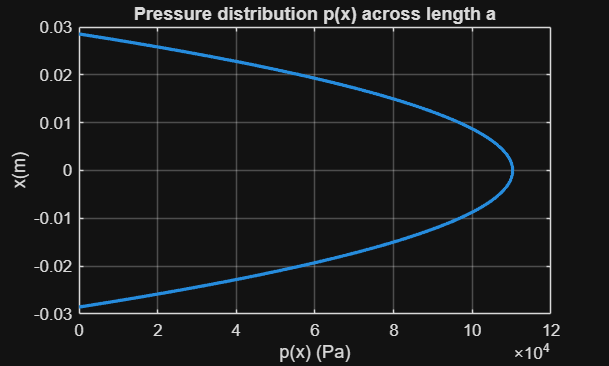

x = linspace(-a/2, a/2, 1000);   % m
sigma = deg2rad(sigma_deg); % rad
tau = deg2rad(tau_deg); % rad
r_dyn = r_dyn_mm*1e-3; % m
CD = CD_mm*1e-3; % m
rs = rs_mm*1e-3; % m
delta = deg2rad(delta_deg); % rad
delta2 = deg2rad(delta_deg2); %rad
m_t = r_dyn*tan(tau); % caster trail / mecanical trail
% Pressure Distribution
p = (6*Fz/(a^3*b)) .* (a/2 - x) .* (a/2 + x);  % Pa (N/m^2)

plot(p, x, 'LineWidth', 2)
grid on
xlabel('p(x) (Pa)')
ylabel('x(m)')
title('Pressure distribution p(x) across length a')

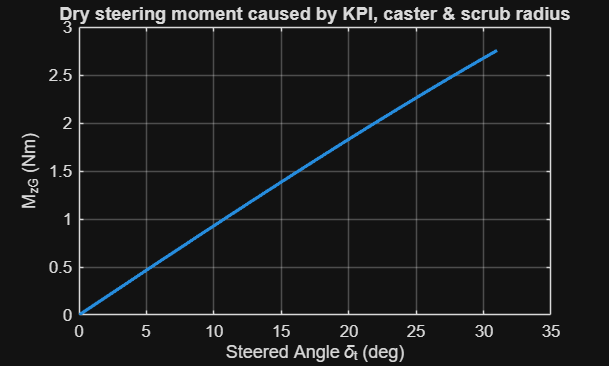


% Gravity based aligning moment
MzG = Fz * (rs + r_dyn*tan(sigma)) .* cos(sigma) .* sin(sigma) .* cos(tau) .* sin(delta2); % Nm
MzG = Fz * (rs + r_dyn*tan(sigma) + m_t) .* cos(sigma) .* sin(sigma) .* cos(tau) .* sin(delta2); % Nm

figure
plot(delta_deg2, MzG, 'LineWidth', 2)
grid on
xlabel('Steered Angle \delta_t (deg)')
ylabel('M_{zG} (Nm)')
title('Dry steering moment caused by KPI, caster & scrub radius')


% Friction based moment
x0 = -a/2;
x1 = a/2;
y0 = -b/2; 
y1 = b/2; 

e0 = 24.03e-3; %m
beta = 10; %degrees

ex = e0*cosd(beta);
%ex = ex + trail; 
ey = e0*sind(beta);
mu = 1.75; %friction coeff

fun = @(x,y) ((6*Fz)/(a^3*b) .* (a/2 - x) .* (a/2 + x)).*(sqrt((ex - x).^2 + (ey - y).^2));

Mzft = mu * integral2(fun, x0, x1, y0, y1);

Mzf = Mzft*cos(sigma);%*cos(tau); %Nm
%Mzf = Mzf/1000; %Nm
Mfo = 0.4; %Nm
D = 40e-3; %m

Lk = 84.55e-3; %m
theta_tk = linspace(107.55, 84.17,1000); %degrees
theta_tk = deg2rad(theta_tk);
theta_rt = linspace(179.95,179.59,1000); %degrees
theta_rt = deg2rad(theta_rt);
theta_kk = deg2rad(68.54); %degrees
Frt = 1; %N ÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆ
R = D/2; %m
L = Lk .* sin(theta_tk);
Ftt = Frt .* cos(pi-theta_rt);
i = (Ftt .* L .* cos(theta_kk-(pi/2)))/(Frt .* R);

Mz = 2*((Mzf+MzG)./i) + Mfo

Mz =    29.3046   29.3025   29.3003   29.2981   29.2959   29.2938   29.2916   29.2895   29.2873   29.2852   29.2830   29.2809   29.2788   29.2767   29.2745   29.2724   29.2703   29.2682   29.2661   29.2640   29.2620   29.2599   29.2578   29.2557   29.2537   29.2516   29.2496   29.2475   29.2455   29.2434   29.2414   29.2394   29.2374   29.2353   29.2333   29.2313   29.2293   29.2273   29.2253   29.2234   29.2214   29.2194   29.2174   29.2155   29.2135   29.2116   29.2096   29.2077   29.2058   29.2038


max(Mz)

ans = 29.5116

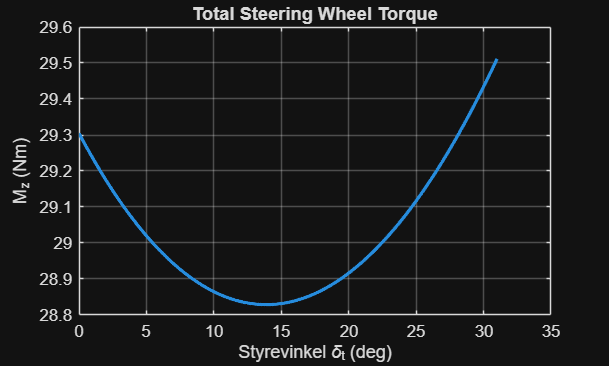

figure
plot(delta_deg2, Mz, 'LineWidth', 2)
grid on
xlabel('Styrevinkel \delta_t (deg)')
ylabel('M_{z} (Nm)')
title('Total Steering Wheel Torque')